Class - April 5th, 2023

First, we define a LTI system in state space representation:

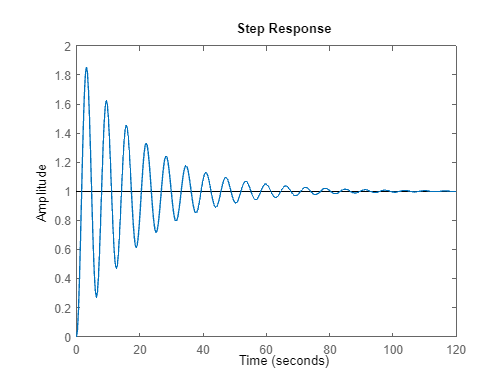

clear all; close all;
num = 1;
den = [1 0.1 1]; % STABLE CASE
%den = [1 -0.1 1]; % UNSTABLE CASE
[A,B,C,D] = tf2ss(num,den);
G = ss(A,B,C,D);
step(G)

Lyapunov Stability - Analysis:

P = sdpvar(length(A));
sdisplay(P);

LMI1 = [A'*P+P*A<=0];
LMI2 = [P>=0];

LMI = [LMI1,LMI2];

optimize(LMI)

SeDuMi 1.3.5 by AdvOL, 2005-2008 and Jos F. Sturm, 1998-2003.
Alg = 2: xz-corrector, theta = 0.250, beta = 0.500
eqs m = 3, order n = 5, dim = 9, blocks = 3
nnz(A) = 9 + 0, nnz(ADA) = 9, nnz(L) = 6
 it :     b*y       gap    delta  rate   t/tP*  t/tD*   feas cg cg  prec
  0 :            5.83E+00 0.000
  1 :   0.00E+00 5.63E-01 0.000 0.0966 0.9900 0.9900   1.00  1  0  4.2E-01
  2 :   0.00E+00 4.06E-02 0.000 0.0722 0.9900 0.9900   1.00  1  1  3.1E-02
  3 :   0.00E+00 8.18E-04 0.000 0.0201 0.9900 0.9900   1.00  1  1  6.2E-04
  4 :   0.00E+00 1.63E-05 0.000 0.0200 0.9900 0.9900   1.00  1  1  1.2E-05
  5 :   0.00E+00 3.26E-07 0.000 0.0200 0.9900 0.9900   1.00  1  1  2.5E-07
  6 :   0.00E+00 6.50E-09 0.000 0.0200 0.9900 0.9900   1.00  1  1  4.9E-09
  7 :   0.00E+00 1.30E-10 0.000 0.0200 0.9900 0.9900   1.00  1  1  9.8E-11

iter seconds digits       c*x               b*y
  7      0.4   Inf  0.0000000000e+00  0.0000000000e+00
|Ax-b| =   3.5e-11, [Ay-c]_+ =   0.0E+00, |x|=  5.2e-11, |y|=  2.6e+

ans = struct with fields:
    yalmipversion: '20210331'
    matlabversion: '9.14.0.2206163 (R2023a)'
       yalmiptime: 1.2643
       solvertime: 0.5637
             info: 'Successfully solved (SeDuMi-1.3)'
          problem: 0


Checking if the initial conditions were satisfied:

Ps = value(P); % or double(P)
eig(Ps);
eig(A)

ans =   -0.0500 + 0.9987i
  -0.0500 - 0.9987i


checkset(LMI);

 
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|          Constraint|   Primal residual|   Dual residual|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|   Matrix inequality|           0.16608|      2.5298e-11|
|   #2|   Matrix inequality|            1.7227|      1.5217e-11|
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
| A primal-dual optimal solution would show non-negative residuals.|
| In practice, many solvers converge to slightly infeasible    |
| solutions, which may cause some residuals to be negative.    |
| It is up to the user to judge the importance and impact of   |
| slightly negative residuals (i.e. infeasibilities)           |
| https://yalmip.github.io/command/check/                      |
| https://yalmip.github.io/faq/solutionviolated/               |
++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 


eig(A'*Ps+Ps*A);